# Dynamic programming for the energy management of a simple fuel cell hybrid electric vehicle

This program shows how to implement a raw dynamic programming to solve the energy management problem for a simple fuel cell hybrid electric vehicle. 

## Load 

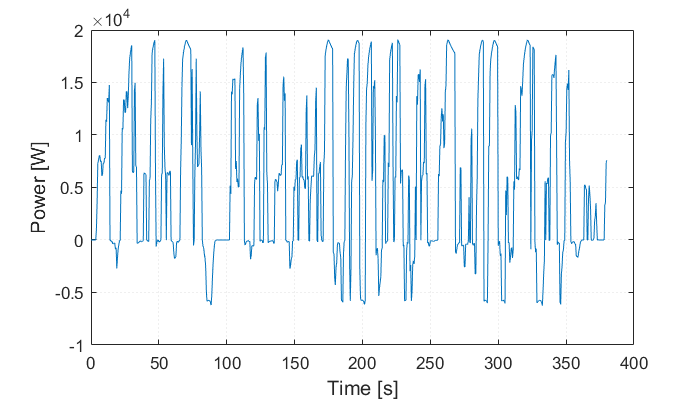

clear all; 
clc; 
close all;
% load driving cycle, this is a driving cycle imported from VTS challenge
% 2017
load('Power_FCV_demande.mat')
% the original sample period is 0.005s. down sampling by 0.5/0.005 = 100 the
% control period is then 0.5s
T_demand = P.time(1:100:end); 
P_demand = P.signals.values(1:100:end,1); % here the original data are multiplied by 3.5 in order to have an adaptive scale
% the overall look of the load power shape
figure
plot(T_demand,P_demand)
xlabel('Time [s]');
ylabel('Power [W]');
set(get(gca,'XLabel'),'FontSize',12);%
set(get(gca,'YLabel'),'FontSize',12);
set(get(gca,'ZLabel'),'FontSize',12);
set(gcf,'position',[232   246   560   320])
set(gca,'XGrid','on','YGrid','on','GridLineStyle',':');


% the length of the load power time series
L = length(P_demand);

% the up and down limits of the final SOC values
SOC_final_min = 70;
SOC_final_max = 75;
state_initial = 70; % initial state value

## Dynamic programming (optimal cost-to-go matrix calculation)

To calculate the optimal cost-to-go matrix, we need to implement a backwards process. 

Net_s = [30:1:75]'; % state discrete vector. state variable: SOC
Net_a = [0:10:400]'; % action discrete vector. action variable: fuel cell current

Num_state = size(Net_s,1); % the total number of discrete state values
Num_action = size(Net_a,1); % the total number of discrete action values
C_t_g = zeros(L+1,Num_state); % initialize the cost-to-go matrix. The size is one more than the number of time instances because we consider the final state cost.

C_t_g(end,:) = func_phi_raw(Net_s,state_initial); % here we need to use phi function to calculate the cost related to the final state. 

% the main loop of backwards cost-to-to matrix calculation, so we loop the
% time instance (k) from the end (L) to the beginning (1)
for k = L:-1:1
    % here at time k, we will use the system dynamic function (func_L_raw) to
    % calculate the instantenous cost (cost_temp), the next-instance state (state_out_temp) and some
    % intermediate variables (output_temp) using all possible action
    % (Net_a) and state (Net_s). 
    % the output size of both cost_temp and state_out_temp are
    % Num_state*Num_action
    [cost_temp, state_out_temp, output_temp] = func_L_raw(Net_a, Net_s, P_demand(k));
    % here we need to find the optimal cost-to-to value related to
    % state_out_temp using interpolation function. We should also permit
    % expolation. 
    C_t_g_temp = interp1(Net_s,C_t_g(k+1,:),state_out_temp,'spline');
    % here we select the minimum cost-to-go value among all values related to different actions and save it into the optimal cost-to-go matrix 
    [C_t_g(k,:),index_a_temp] = min(cost_temp+C_t_g_temp,[],2);
end

## Forward simulation

Here we will use the calculated cost-to-go matrix to plan the action sequence. 

%% foreward simulation
action_opt = zeros(L,1); % we initialize the optimal action sequence
Cost_opt = zeros(L,1); % we initialize the optimal instantenous cost sequence
State_opt = zeros(L+1,1);  % we initialize the state sequence which is 1 more than L

State_opt(1,:)= state_initial; % we put the initial state into the vector
% here we loop the time instance from the beginning to the end
for k = 1:L
    % at time k, we calculate the instantenous costs (cost_temp) and next-instance states (state_out_temp) related to all actions
    % standing on the current state. 
    [cost_temp, state_out_temp, output_temp] = func_L_raw(Net_a, State_opt(k), P_demand(k));
    % we calculate the optimal cost-to-go values related to state_out_temp
    C_t_g_temp = interp1(Net_s,C_t_g(k+1,:),state_out_temp);
    % we select the action which yields the minimum cost-to-go value (cost_temp+C_t_g_temp) from
    % the current state 
    [C_t_fwd_temp,index_a_temp] = min(cost_temp+C_t_g_temp,[],2);
    % put the corresponding next-instance state into the vector for saving
    State_opt(k+1) = state_out_temp(index_a_temp);
    action_opt(k) = Net_a(index_a_temp); % save the optimal action
    Cost_opt(k) = cost_temp(index_a_temp); % save the optimal instantenous cost
end

## Print and plot results

%--------------------------------------------------------------------------
% PLOT RESULTS:
%--------------------------------------------------------------------------
%Calculate Optimal Solution:
fprintf('The total cost is %s', sum(Cost_opt))

The total cost is 4.528856e+01

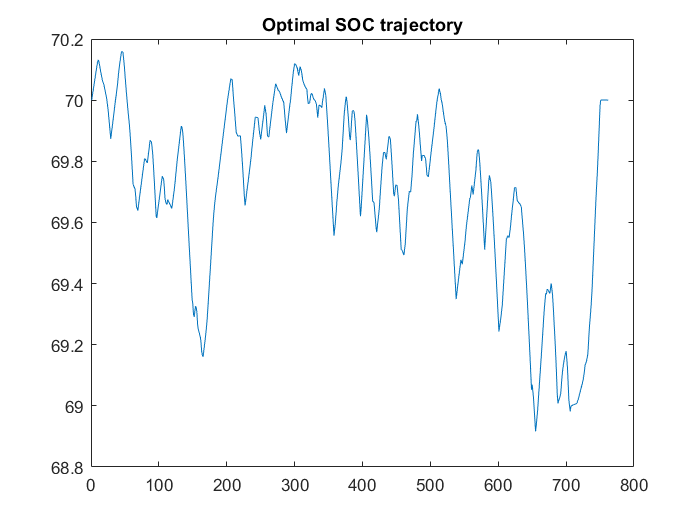

figure
plot(State_opt)
title('Optimal SOC trajectory')

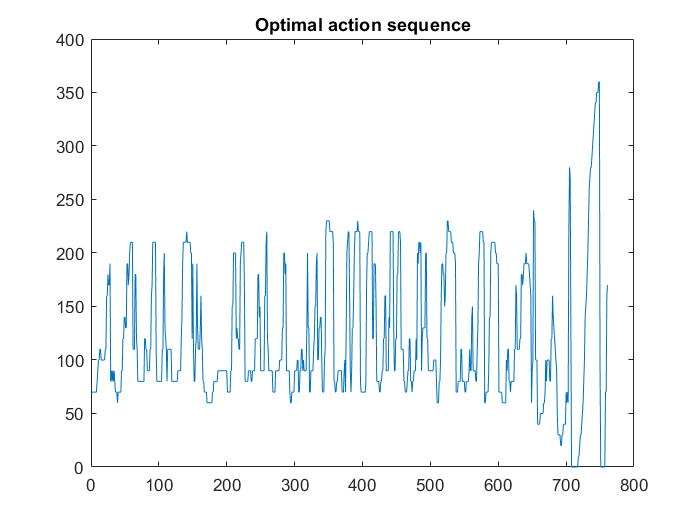

figure
plot(action_opt)
title('Optimal action sequence')

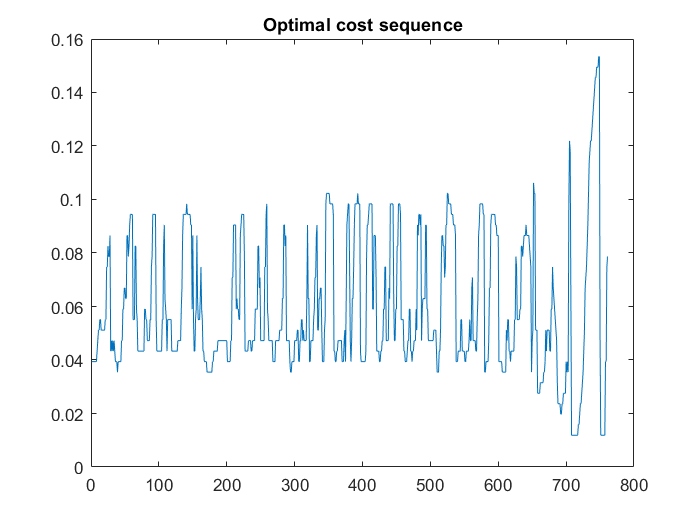

figure
plot(Cost_opt)
title('Optimal cost sequence')